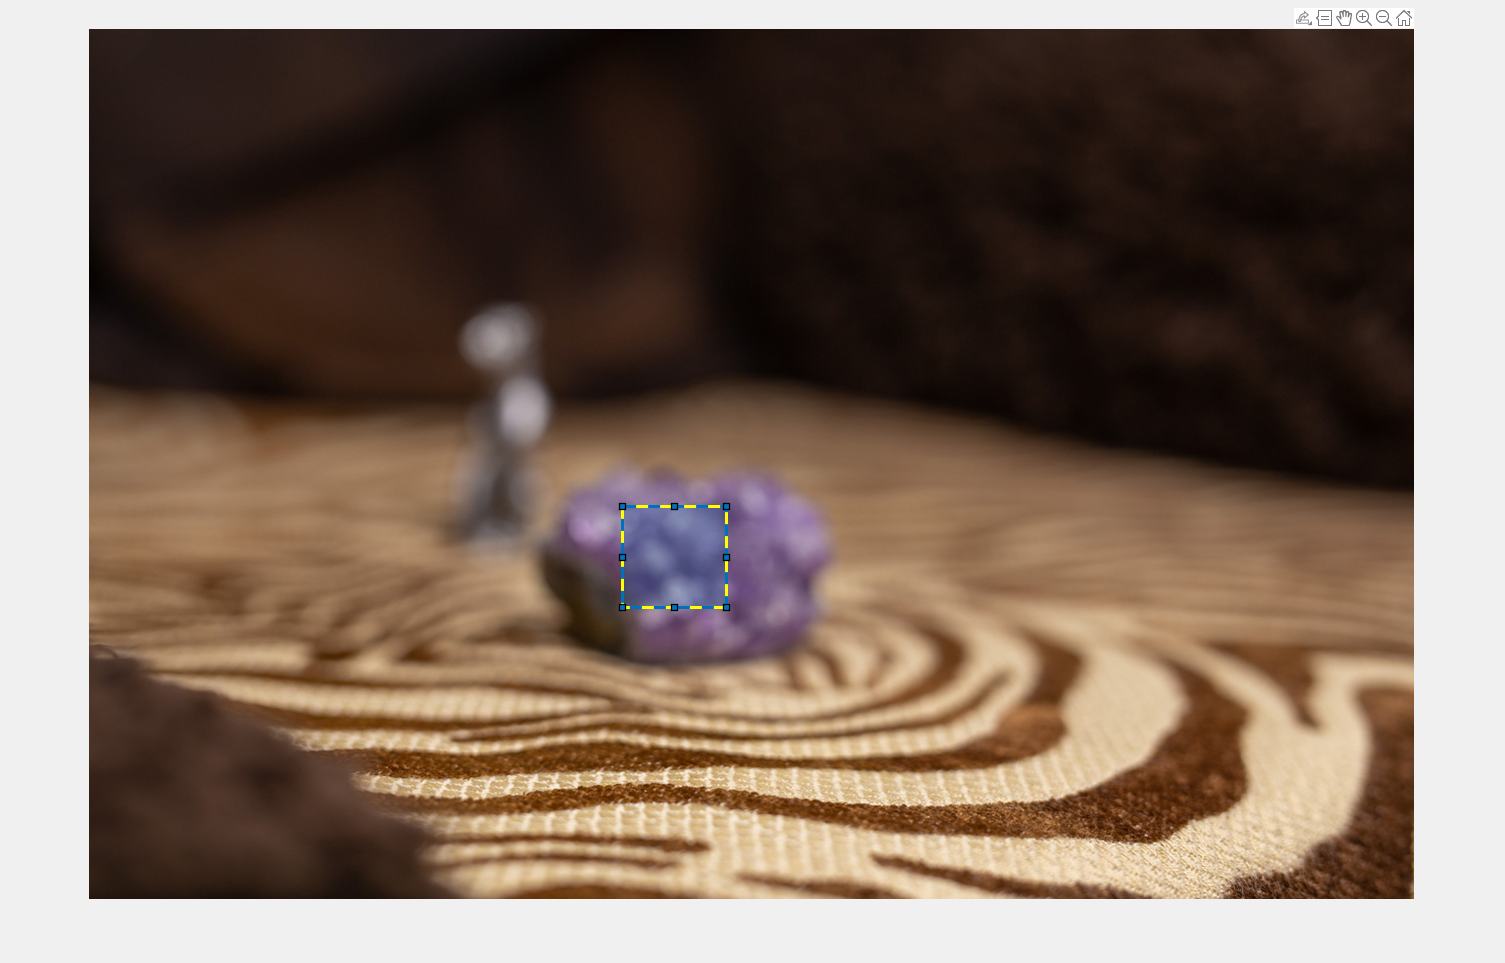

%Decide what image series to use
%'TestImages\Geode\';
%'TestImages\Cactus\';
%'TestImages\Card\';

%create a vector with the names
pictures = ["0", '1', '2', '3','4', '5', '6','7', '8', '9','10', '11', '12','13', '14', '15', '16', '17', '18', '19', '20', '21', '22', '23', '24', '25', '26'];

im_box = imread('TestImages\Geode\0.jpg');
imshow(im_box)
roi = drawrectangle('StripeColor','y');


%Set the block size we want to use
N = roi.Vertices(2,2) -  roi.Vertices(1,2); 
M = roi.Vertices(3,2) -  roi.Vertices(4,2); 

i =  round((roi.Vertices(1,1) + roi.Vertices(3,1))/2); %Alla rader
j =  round((roi.Vertices(1,1) + roi.Vertices(1,2))/2); %Alla columner

roi_temp = roi.Position;

%Place for adding noise etc if we want

%SML (Gives same value for all, probably wrong)
smlRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Geode\' + pictures(x) + '.jpg');
    smlRes(x) = SML(im_x, i, j, N);
end


We don't actually know what to expect out of these so it's difficult to know whether the values we are getting seem logical or not.

%EOL
eolRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Geode\' + pictures(x) + '.jpg');
    im_temp = imcrop(im_x,roi_temp);
    eolRes(x) = EOL(im_temp);
end


%EOG
eogRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Geode\' + pictures(x) + '.jpg');
    im_temp = imcrop(im_x,roi_temp);
    eogRes(x) = EOG(im_temp);
end


%SF 
sfRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Geode\' + pictures(x) + '.jpg');
    im_temp = imcrop(im_x,roi_temp);
    sfRes(x) = SF(im_temp);
end


%Tenengrad (Not implemented)
tenRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Geode\' + pictures(x) + '.jpg');
    im_temp = imcrop(im_x,roi_temp);
    tenRes(x) = Tenengrad(im_temp);
end



%Variance (Not implemented)
varRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Geode\' + pictures(x) + '.jpg');
    im_temp = imcrop(im_x,roi_temp);
    varRes(x) = Variance(im_temp);
end



%Plot them all



